% Seth Kantz and Matthew Delafield
% EE6760

clear;
clc;
close all;


% Set random seed
rng(621);

% Define setup for the test
numDevices = 2;
numElements = 4;
a1 = 1.0;
a3_nominal = 0.02;

variation = 0.15;
a3 = a3_nominal * (1 + variation * randn(numDevices, numElements));



% Gen RIS configurations 16x4 matrix, each rows a challenge
configs = dec2bin(0:15) - '0';

% gen the RF Excitation
Fs = 1e6;
N = 10000;

t = (0:N-1)/Fs;

f1 = 100e3;
f2 = 120e3;

A1 = 0.5;
A2 = 0.5;

x = A1*cos(2*pi*f1*t) + A2*cos(2*pi*f2*t);



% Execute Challenges
for d = 1:numDevices
    for c = 1:size(configs,1)
        states = configs(c,:);
        y = RISDevice(x,states,a1,a3(d,:));
        features(d,c,:) = PIMExtraction(y,Fs,f1,f2);
    end
end



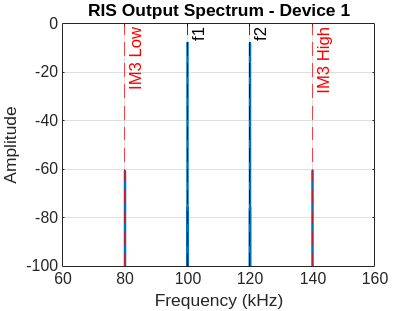

% Generate Frequency Spectrum Graph


% Select first RIS device and first configuration
device_idx = 1;
config_idx = 1;

states = configs(config_idx,:);

% Generate output signal
y = RISDevice(x, states, a1, a3(device_idx,:));

% Calculate FFT
Y = fft(y);
Nfft = length(y);

% One-sided amplitude spectrum
freq = (0:floor(Nfft/2)) * Fs/Nfft;

amplitude = 2*abs(Y(1:length(freq)))/Nfft;

% Correct DC and Nyquist scaling
amplitude(1) = amplitude(1)/2;
if mod(Nfft,2) == 0
    amplitude(end) = amplitude(end)/2;
end

% Expected PIM locations
fIM3_1 = 2*f1 - f2;
fIM3_2 = 2*f2 - f1;

% Plot output spectrum
figure(1);
plot(freq/1e3,20*log10(max(amplitude,1e-12)),'LineWidth', 1.5);
ylabel('Amplitude (dB)');
ylim([-100 0]);grid on;
xlabel('Frequency (kHz)');
ylabel('Amplitude');
title('RIS Output Spectrum - Device 1');

% Focus on frequencies of interest
xlim([60 160]);

% Mark frequencies
xline(fIM3_1/1e3, '--r', 'IM3 Low');
xline(f1/1e3, '--k', 'f1');
xline(f2/1e3, '--k', 'f2');
xline(fIM3_2/1e3, '--r', 'IM3 High');

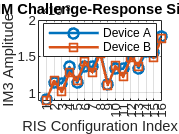

% Generate PIM signature vs RIS

numConfigs = size(configs, 1);

% Store IM3 amplitudes for both devices
pimResults = zeros(numDevices, numConfigs);

for d = 1:numDevices
    % run the same config for each device
    for c = 1:numConfigs

        % select RIS config
        states = configs(c,:);

        % Simulate RIS response
        y = RISDevice(x, states, a1, a3(d,:));

        % extract IM3 features
        features = PIMExtraction(y, Fs, f1, f2);

        % store extracted lower im3
        pimResults(d,c) = features(1);

    end
end

% Plot results
figure(2);

plot(1:numConfigs, pimResults(1,:), '-o','LineWidth', 1.5);
hold on;
plot(1:numConfigs, pimResults(2,:), '-s','LineWidth', 1.5);

grid on;
xlabel('RIS Configuration Index');
ylabel('IM3 Amplitude');
title('RIS-PIM Challenge-Response Signatures');

legend('Device A', 'Device B', ...
    'Location', 'best');

xticks(1:numConfigs);
hold off;